# **RS-HL-13: Multi User Default Code**

**Hongseok Kim**

**UT Austin Oden Institute**

**07/20/24**

### **I. Load the Dataset**

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('~/RS_Dataset/RS_HL_3_dataset.mat')

### II. Destination Setting and Time Index Vector Setting

time_index_vector = 100:130;
start_time_index = 100:120;
% 
% destination_1 = 10;
% destination_2 = 12;
% destination_3 = 18;
% destination_4 = 27;
% destination_5 = 40;


number_of_agents = 25;
number_of_destinations = 4;
state_vector = 1:48;


start_state = state_vector(randi(numel(state_vector), 1, number_of_agents));
destination_values = randsample(state_vector,number_of_destinations);
destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
start_time = start_time_index(randi(numel(start_time_index), 1, number_of_agents));

#### II.1 Run the MDP simulation for each destination


number_of_destination = length(destination_values);

for destination_index = 1:number_of_destination

    MDP.(['MDP', num2str(destination_values(destination_index))]) = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_values(destination_index));

end

simulation set up complete! 
Policy: 1 -> Value Iteration: 277
Policy: 2 -> Value Iteration: 4
Policy: 3 -> Value Iteration: 2
Policy: 4 -> Value Iteration: 3
Policy: 5 -> Value Iteration: 3
Policy: 6 -> Value Iteration: 7
Policy: 7 -> Value Iteration: 2
Policy: 8 -> Value Iteration: 2
simulation set up complete! 
Policy: 1 -> Value Iteration: 299
Policy: 2 -> Value Iteration: 5
Policy: 3 -> Value Iteration: 2
Policy: 4 -> Value Iteration: 3
Policy: 5 -> Value Iteration: 7
Policy: 6 -> Value Iteration: 8
Policy: 7 -> Value Iteration: 6
Policy: 8 -> Value Iteration: 2
Policy: 9 -> Value Iteration: 2
Policy: 10 -> Value Iteration: 2
Policy: 11 -> Value Iteration: 2
Policy: 12 -> Value Iteration: 2
simulation set up complete! 
Policy: 1 -> Value Iteration: 278
Policy: 2 -> Value Iteration: 5
Policy: 3 -> Value Iteration: 3
Policy: 4 -> Value Iteration: 3
Policy: 5 -> Value Iteration: 4
Policy: 6 -> Value Iteration: 7
Policy: 7 -> Value Iteration: 6
Policy: 8 -> Value Iteration: 2
Policy: 

### III. Configure each Agent's Setting

agents_input = [start_time', start_state', destination_state'];

### IV. Configure the simulation structure setting

% Level 1: Initialize simulation structure
sim = struct();

for time_index = time_index_vector
    sim.(['time' num2str(time_index)]) = {};
end

% Level 2/3: Initialize Agent (Level 2) with States and Destination (Level 3)

number_of_agents = length(agents_input(:,1));

for agent_index = 1:number_of_agents
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('state') = agents_input(agent_index,2);
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('destination') = agents_input(agent_index,3);   
end


### V. Propagation of agents' state

collision_flag = false;

for time_index = time_index_vector

    % If there's no active agent, continue to next time step
    if isempty(sim.(['time' num2str(time_index)]))
       continue;
    end


    % Parse the number of active agents
    number_of_active_agents = length(fieldnames(sim.(['time' num2str(time_index)])));

    % Make the status matrix represents current and next
    % [current_state, next_state, destination]
    status_matrix = zeros(3, number_of_active_agents);

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));

    % Find the Next state from Current Agent-State 
    for active_agent_index = 1:number_of_active_agents
        % Find the Current State and Destination of given agent
        current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
        destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');

        % Find the Next state from given MDP pi distribution
        pi_dist = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).('policy_distribution');
        action_number = find(pi_dist(current_state,:) ~= 0);

        if length(action_number) > 1
        action_number = randsample(action_number,1);
        end

        next_state = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('next_state');
        reward = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');
        state_value =  MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).('state_value');
        action_value  = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('action_value'); 

        % Configure Proposed status matrix for the collision test
        status_matrix(1,active_agent_index) = current_state;
        status_matrix(2,active_agent_index) = next_state;
        status_matrix(3,active_agent_index) = destination;

        % Add State Value
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state_value') = state_value;

        % Save the Original Reward and action value to prepare the update
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_number') = action_number;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_reward') = reward;

        % Add the action number, reward, action value (may be changed)
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_number') = action_number;        
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('reward') = reward;
    end


    % Break when time index reaches the end time
    if time_index == max(time_index_vector)
       break;
    end

    for active_agent_index = 1:number_of_active_agents

        % Don't update the agent already arrived to destination
        if status_matrix(1,active_agent_index) ==  status_matrix(3,active_agent_index)
            continue;
        end

        % Update the time+1 for next state
        sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('state') = status_matrix(2,active_agent_index);
        sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('destination') = status_matrix(3,active_agent_index);       
    end
end

### VI. result display

result_matrix = zeros(length(time_index_vector),number_of_agents);
reward_matrix =  zeros(length(time_index_vector),number_of_agents);
state_value_matrix = zeros(length(time_index_vector),number_of_agents);
action_value_matrix = zeros(length(time_index_vector),number_of_agents);
cumulative_reward_matrix = zeros(length(time_index_vector),number_of_agents);

for time_index = time_index_vector

    if isempty(sim.(['time' num2str(time_index)]))
     continue;
    end

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));
    number_of_agents = length(agents_list);

    for agent_index = 1:number_of_agents
        agent_name = cell2mat(agents_list(agent_index));
        agent_no = regexp(agent_name, '\d+','match');
        agent_number = str2double(agent_no{1});

        result_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state');
        reward_matrix(time_index - min(time_index_vector) + 1,agent_number) =  sim.(['time' num2str(time_index)]).(agent_name).('reward');
        state_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state_value');
        action_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('action_value');
        cumulative_reward_matrix(time_index - min(time_index_vector) + 1,agent_number) = sum(reward_matrix(1:time_index - min(time_index_vector) + 1,agent_number));

    end

end

result = [time_index_vector' , result_matrix]

result =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0    47     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0    48     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   104     0    44     0     0     0     0     0     0     0    25    31     0     0     0     0     0     0     0    39     0     0     0     0     0     0
   105     0    43     0    44     0     0     0     0     0    26    32    47     0    24     0     7     0     0    38    47     0     0     0     0     0
   106     0    42     0    43     0     0     0 

reward = [time_index_vector', reward_matrix]

reward =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0    -1   -15     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   104     0    -1     0     0     0     0     0     0     0    -1    75     0     0     0     0     0     0     0    -1     0     0     0     0     0     0
   105     0    -1     0    -1     0     0     0     0     0    -1     0    -1     0    -1     0   -15     0     0    75    -1     0     0     0     0     0
   106     0    -1     0    -1     0     0     0 

cumulative_reward = [time_index_vector', cumulative_reward_matrix]

cumulative_reward =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0    -2   -15     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   104     0    -1     0     0     0     0     0     0     0    -3    60     0     0     0     0     0     0     0    -1     0     0     0     0     0     0
   105     0    -2     0    -1     0     0     0     0     0    -4    60    -1     0    -1     0   -15     0     0    74    -1     0     0     0     0     0
   106     0    -3     0    -2     0  

state_value = [time_index_vector', state_value_matrix]

state_value =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0    67     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0    68    60     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   104     0    68     0     0     0     0     0     0     0    69    75     0     0     0     0     0     0     0    74     0     0     0     0     0     0
   105     0    69     0    69     0     0     0     0     0    70     0    65     0    84     0    57     0     0    75    66     0     0     0     0     0
   106     0    70     0    70     0     0  

action_value = [time_index_vector', action_value_matrix]

action_value =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0    67     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0    68    60     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   104     0    68     0     0     0     0     0     0     0    69    75     0     0     0     0     0     0     0    74     0     0     0     0     0     0
   105     0    69     0    69     0     0     0     0     0    70     0    65     0    84     0    57     0     0    75    66     0     0     0     0     0
   106     0    70     0    70     0     0 

### VII. Result Graph

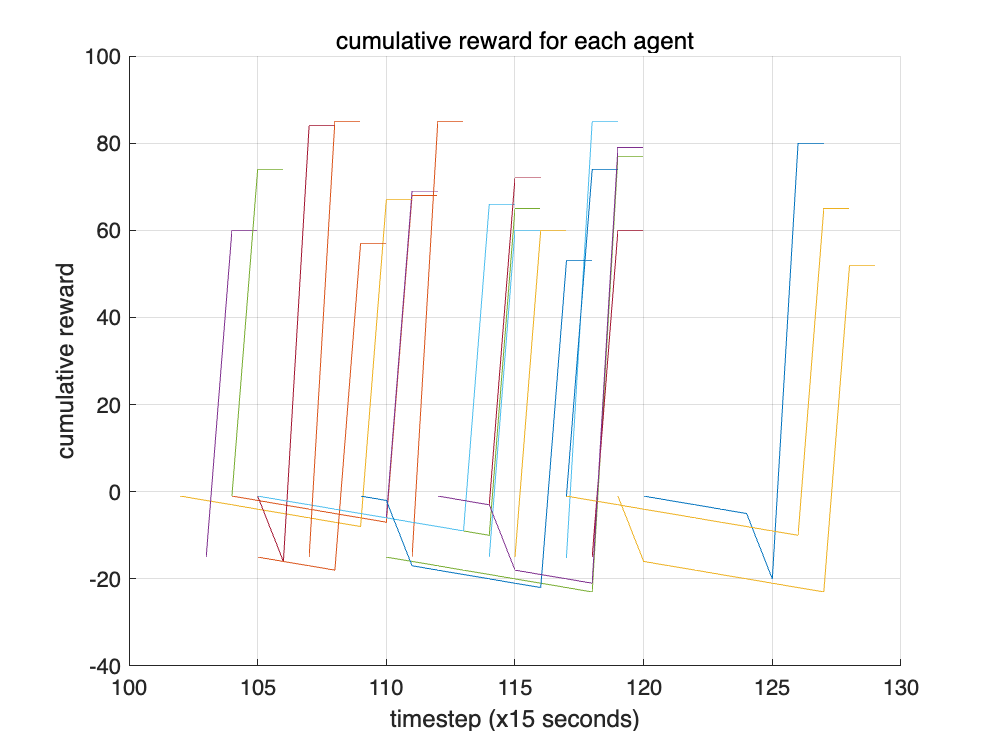

number_of_agents = length(agents_input(:,1));

figure;
hold on
for agent_index = 1:number_of_agents

    cumulative_reward_each_agent = [time_index_vector', cumulative_reward_matrix(:,agent_index)];
    cumulative_reward_each_agent = cumulative_reward_each_agent(cumulative_reward_each_agent(:,2) ~= 0, :);
    
   plot(cumulative_reward_each_agent(:,1),cumulative_reward_each_agent(:,2))
   
end
hold off
grid on
title('cumulative reward for each agent')
xlabel('timestep (x15 seconds)')
ylabel('cumulative reward')

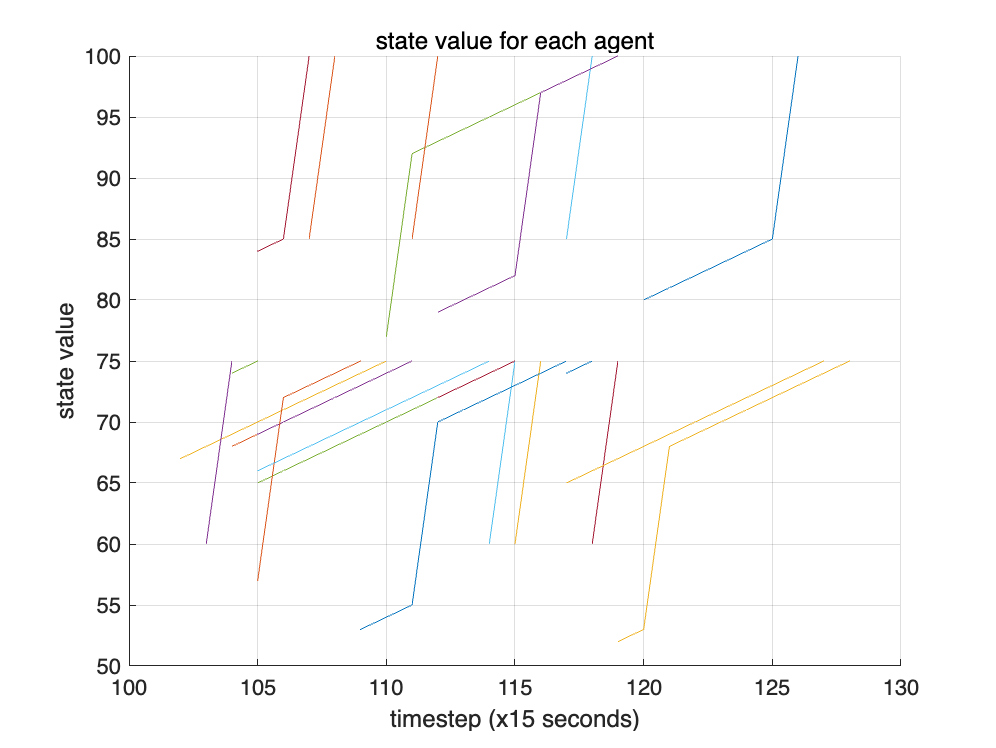


figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2))
end
hold off
grid on
title('state value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('state value')

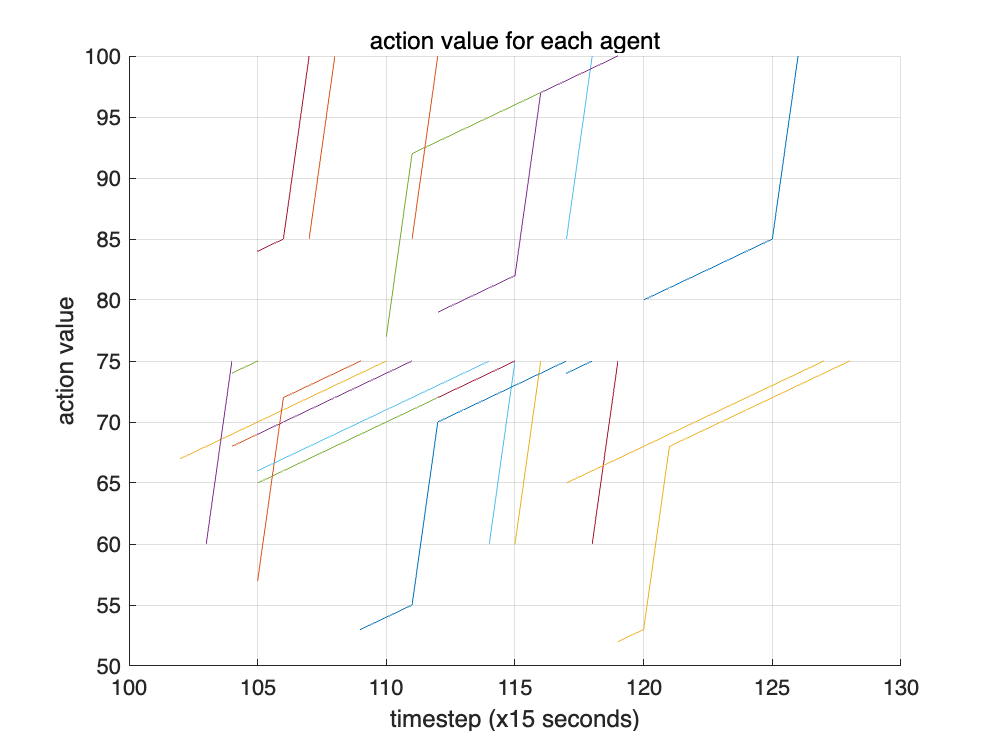


figure;
hold on
for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2))
end
hold off
grid on
title('action value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('action value')

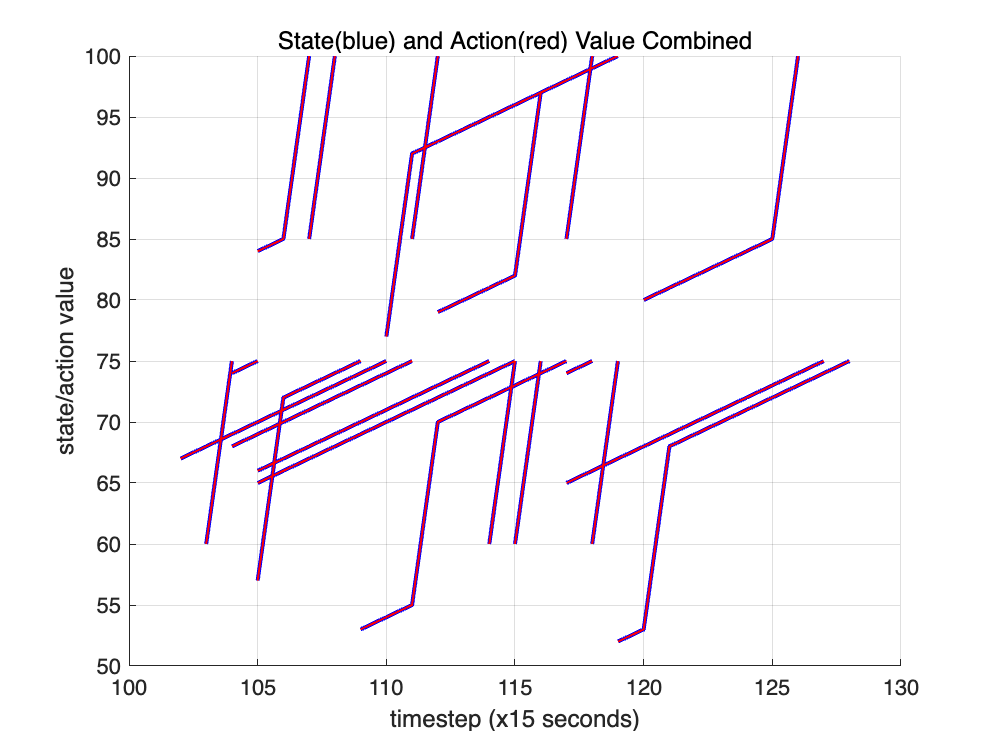




figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2),'b','LineWidth',2)
end


for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2),'r','LineWidth',1)
end
hold off
grid on
title('State(blue) and Action(red) Value Combined')
xlabel('timestep (x15 seconds)')
ylabel('state/action value')